x=[1;1];
A=[1 1;
   0 1];
P=[1 0;
   0 1];
x_pre=A*x

x_pre =      2
     1


P_pre=A*Q*A'

P_pre =      2     1
     1     1


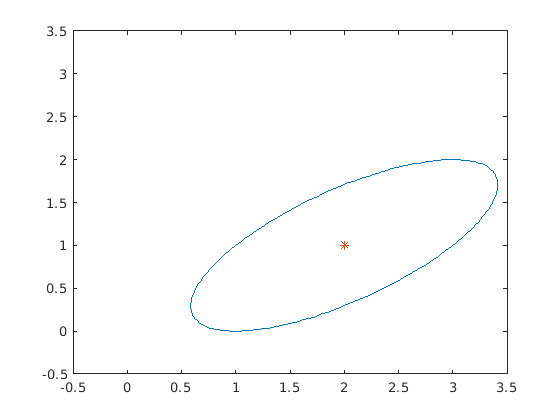

xy = sigmaEllipse2D(x_pre, P_pre,1, npoints);
figure(1);
h2 = plot(xy(1,:), xy(2,:));
hold on
plot(x_pre(1),x_pre(2),'*')
hold off
axis([-0.5 3.5 -0.5 3.5])

%2*2=4, 4 points in total
P_sqrt=chol(P,'lower')

P_sqrt =      1     0
     0     1


sqrt_n=sqrt(2);
Sigma_points=zeros(2,4)

Sigma_points =      0     0     0     0
     0     0     0     0


%i=1
Sigma_points(:,1)=x+sqrt_n*P_sqrt(:,1)

Sigma_points =     2.4142         0         0         0
    1.0000         0         0         0


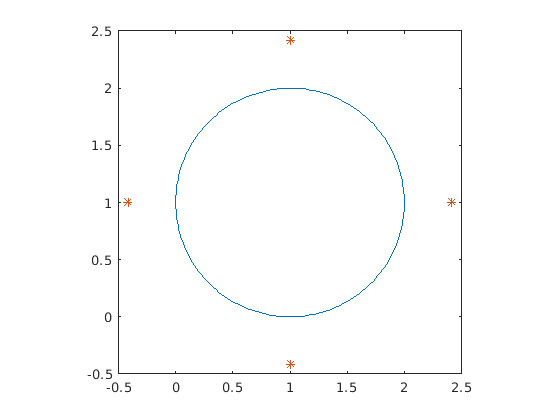

%i=2
Sigma_points(:,2)=x+sqrt_n*P_sqrt(:,2);
%i=1,n=2
Sigma_points(:,3)=x-sqrt_n*P_sqrt(:,1);
%i=2,n=2
Sigma_points(:,4)=x-sqrt_n*P_sqrt(:,2);

xy = sigmaEllipse2D(x,P,1,npoints);
figure(1);
h2 = plot(xy(1,:), xy(2,:));
hold on
plot(Sigma_points(1,:),Sigma_points(2,:),'*')
hold off
axis equal
axis([-0.5 2.5 -0.5 2.5])

W=1/(2*2);
for i=1:4
    Sigma_points_new(:,i)=A*Sigma_points(:,i);
end
x_temp=W*Sigma_points_new;
x_pre=sum(x_temp,2)

x_pre =      2
     1


P_pre=0;
for i=1:4
    temp=W*(Sigma_points_new(:,i)-x_pre)*(Sigma_points_new(:,i)-x_pre)';
    P_pre=P_pre+temp;
end
P_pre

P_pre =      2     1
     1     1


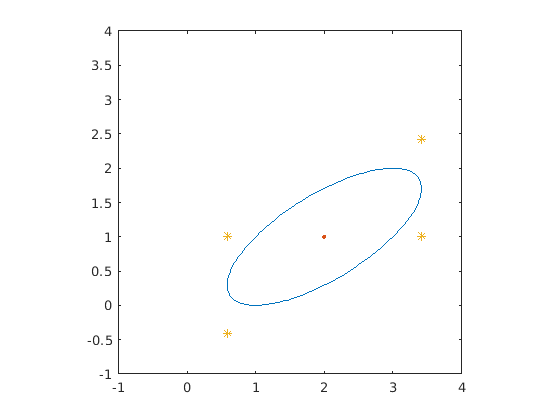

xy = sigmaEllipse2D(x_pre,P_pre,1,npoints);
figure(1);
h2 = plot(xy(1,:), xy(2,:));
hold on
plot(x_pre(1),x_pre(2),'.')
plot(Sigma_points_new(1,:),Sigma_points_new(2,:),'*')
hold off
axis equal
axis([-1 4 -1 4])

test=[1 2 3;1 2 3]

test =      1     2     3
     1     2     3


tt=[1;1]

tt =      1
     1


test-tt

ans =      0     1     2
     0     1     2
